clear
J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
L = 2.75E-6;
R = 4;
s = tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.
모델 속성



P_system = K/(s*((J*s+b) * (L*s+R) +K^2));
r_system = 1;
t_system = 0:0.001:0.3;

Kp = 30;
C = Kp;
sys_cl = feedback(C*P_system,1)

sys_cl =
 
                         0.822
  ---------------------------------------------------
  8.878e-12 s^3 + 1.291e-05 s^2 + 0.0007648 s + 0.822
 
연속시간 전달 함수입니다.
모델 속성


dist_cl = feedback(P_system,C)

dist_cl =
 
                        0.0274
  ---------------------------------------------------
  8.878e-12 s^3 + 1.291e-05 s^2 + 0.0007648 s + 0.822
 
연속시간 전달 함수입니다.
모델 속성


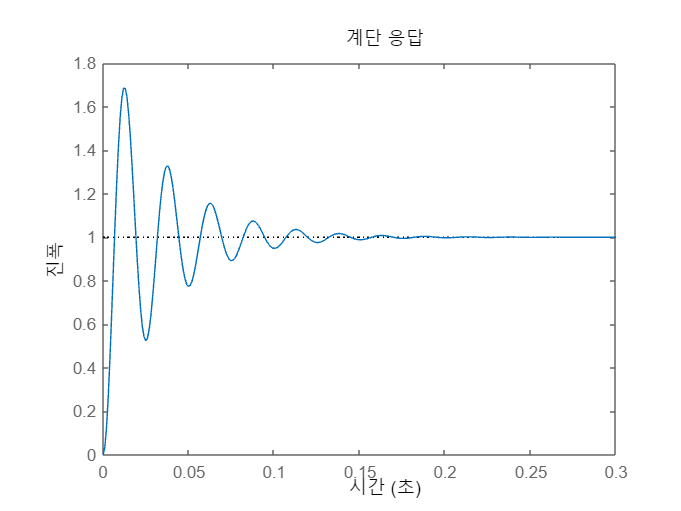

figure(1)
step(r_system*sys_cl,t_system)

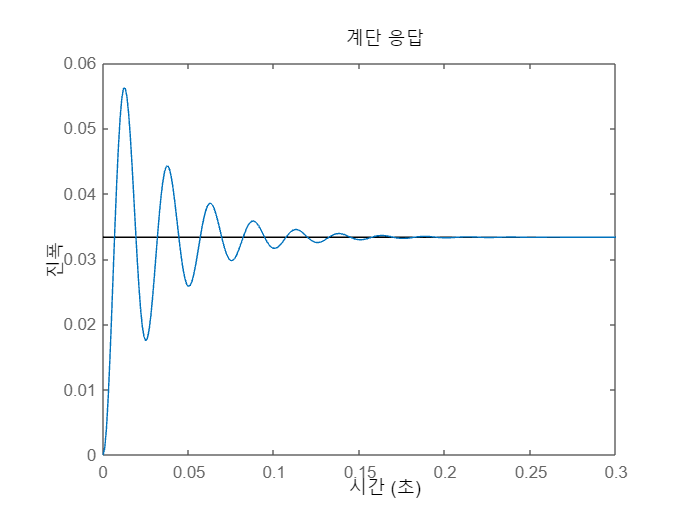

figure(2)
step(dist_cl,t_system)

Kp = 30;
Ki = 1000;
C = Kp+Ki/s;
sys_cl = feedback(C*P_system,1)

sys_cl =
 
                          0.822 s + 27.4
  --------------------------------------------------------------
  8.878e-12 s^4 + 1.291e-05 s^3 + 0.0007648 s^2 + 0.822 s + 27.4
 
연속시간 전달 함수입니다.
모델 속성


dist_cl = feedback(P_system,C)

dist_cl =
 
                             0.0274 s
  --------------------------------------------------------------
  8.878e-12 s^4 + 1.291e-05 s^3 + 0.0007648 s^2 + 0.822 s + 27.4
 
연속시간 전달 함수입니다.
모델 속성


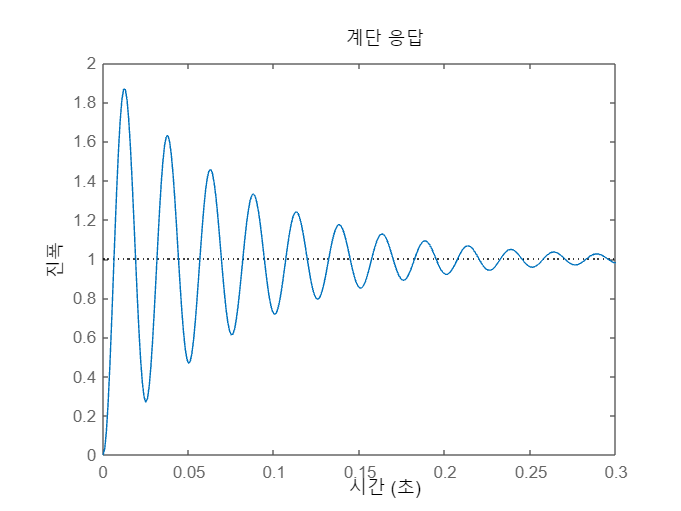

figure(3)
step(r_system*sys_cl,t_system)

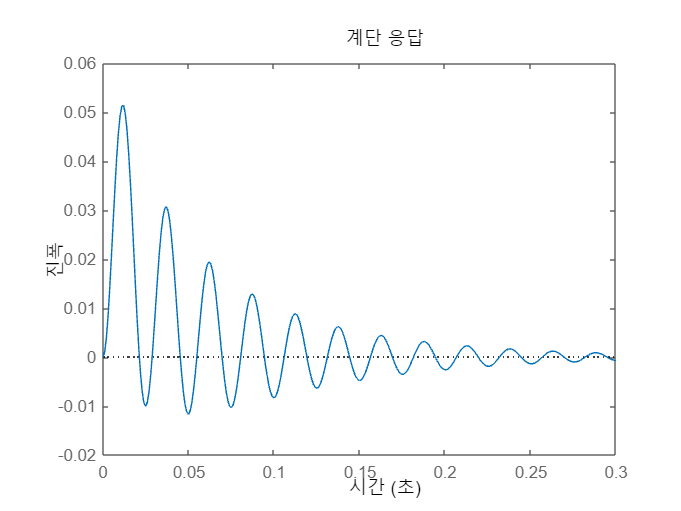

figure(4)
step(dist_cl,t_system)

Kp = 30;
Ki = 1000;
Kd = 0.25;
C = Kp+Ki/s+Kd*s;
sys_cl = feedback(C*P_system,1)

sys_cl =
 
                  0.00685 s^2 + 0.822 s + 27.4
  -------------------------------------------------------------
  8.878e-12 s^4 + 1.291e-05 s^3 + 0.007615 s^2 + 0.822 s + 27.4
 
연속시간 전달 함수입니다.
모델 속성


dist_cl = feedback(P_system,C)

dist_cl =
 
                            0.0274 s
  -------------------------------------------------------------
  8.878e-12 s^4 + 1.291e-05 s^3 + 0.007615 s^2 + 0.822 s + 27.4
 
연속시간 전달 함수입니다.
모델 속성


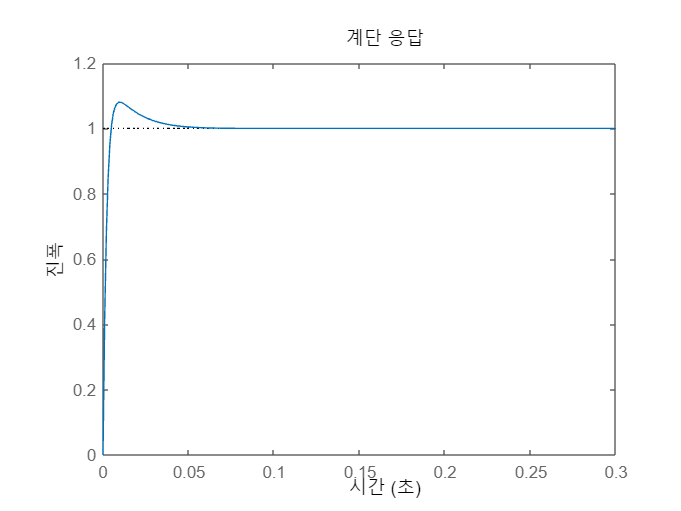

figure(5)
step(r_system*sys_cl,t_system)

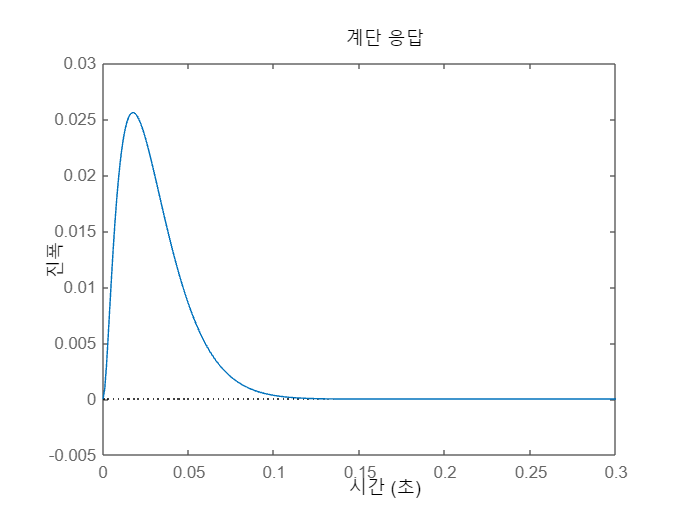

figure(6)
step(dist_cl,t_system)